## ECG-Evoked ERP

% Startup
clear('all');
close('all');

% Caricamento dati
data_dir = fullfile(pwd, 'data');
load(fullfile(data_dir, 'Time_Epochs.mat'));
load(fullfile(data_dir, 'EEG_Good_Epochs.mat'));

% Selezione dati
subj = edfread(fullfile(data_dir, 'eegKY1.edf'));
epoch_EEG = EEG_Good_Epochs.hour01;
epoch_timing = Time_Epochs.epoch01;

fs = 512; % Frequenza di campionamento

ECG_orig = cell2mat(subj{:,16})';

% Pulizia variabili
clear('subj', 'data_dir');

% Creazione vettore di 0 e 1, 1 nelle epoche da selezionare
good_epochs_binary = zeros(1,3600*fs);
% Creazione matrice EEG con 0 nelle epoche da scartare
EEG = zeros(8,3600*fs);
for good_epoch = 1:size(epoch_timing,1)
    wdw = epoch_timing(good_epoch,1)*fs:epoch_timing(good_epoch,2)*fs-1;
    good_epochs_binary(wdw) = 1;
    EEG(:,wdw) = epoch_EEG(:,:,good_epoch);
end

% Filtraggio degli ECG non compatibili con gli spezzoni puliti di EEG
ECG = good_epochs_binary .* ECG_orig;

% Ricerca dei picchi R nel segnale ECG
[~, ECG_locs] = findpeaks(ECG,'MinPeakProminence',300,'MinPeakDistance',60/200);

% Pulizia variabili
clear('good_epochs_binary', 'epoch_EEG', 'epoch_timing', 'EEG_Good_Epochs', ...
    'Time_Epochs', 'good_epoch', 'ECG_orig', 'wdw');

% Selezione degli intervalli da utilizzare intorno al picco R
tau = 0.5; % Durata totale
tau_zero = 0.2; % Offset negativo
tau_EEG_baseline = 0.1; % Durata baseline

ECG_trials = zeros(length(ECG_locs), ceil(tau * fs));
EEG_trials = zeros(length(ECG_locs),ceil(tau*fs),size(EEG,1));
EEG_trials_norm = EEG_trials;
EEG_mean = zeros(size(EEG,1),ceil(tau*fs));
tau_interval = -floor(tau_zero*fs):+floor((tau-tau_zero)*fs);
EEG_baseline_interval = -floor(tau_zero*fs):-floor((tau_zero-tau_EEG_baseline)*fs);
        
for ch = 1:size(EEG,1)
    EEG_baseline = zeros(length(ECG_locs),length(EEG_baseline_interval));
    for peak = 1:length(ECG_locs)
        loc = ECG_locs(peak);
        ECG_trials(peak,:) = ECG(loc+tau_interval);
        EEG_trials(peak,:,ch) = EEG(ch,loc+tau_interval);
        EEG_baseline(peak,:) = EEG(ch,loc+EEG_baseline_interval);
    end
    EEG_mean_baseline = mean(EEG_baseline,2);
    EEG_trials_norm(:,:,ch) = EEG_trials(:,:,ch)-EEG_mean_baseline;
    EEG_mean(ch,:) = mean(EEG_trials_norm(:,:,ch),1);
end

ECG_std = std(ECG_trials,0,1);
EEG_std = squeeze(std(EEG_trials_norm,0,1))';
ECG_mean = mean(ECG_trials,1);

t = -tau_zero:1/fs:tau-tau_zero-1/fs;

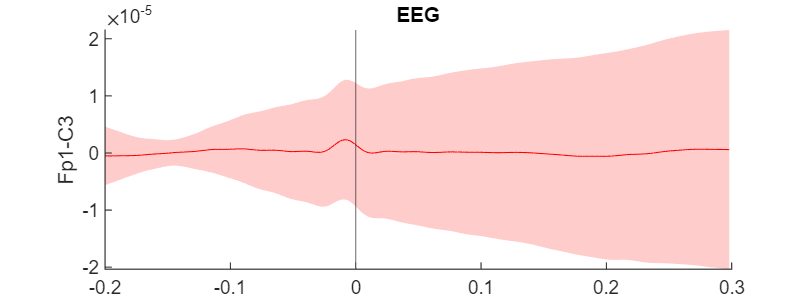

channels = {'Fp1-C3','C3-O1','Fp1-T3',...
    'T3-O1','Fp2-C4','C4-O2','Fp2-T4','T4-O2'};
figure('position',[0 0 800 300]);
ch = 1;
plot(t,EEG_mean(ch,:),'r');
hold on
xline(0);
[y1,y2,~] = fill_between(t,EEG_mean(ch,:)-EEG_std(ch,:),EEG_mean(ch,:)+EEG_std(ch,:),1,...
    'EdgeColor','none','FaceColor',[1 0 0],'FaceAlpha',0.2);
y1.Color = 'none';
y2.Color = 'none';
hold off
ylabel(channels{ch});
box off
title('EEG')

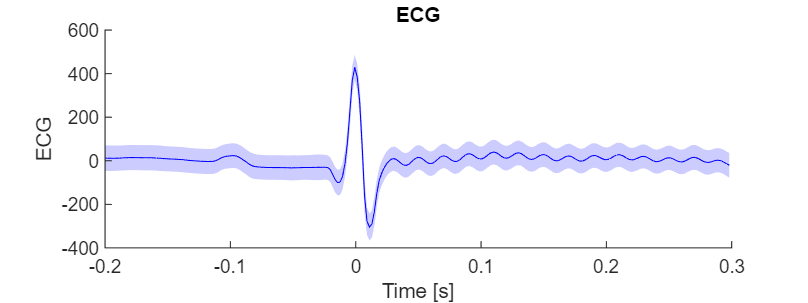



figure('position',[0 0 800 300]);
plot(t,ECG_mean,'b');
xlabel('Time [s]')
ylabel('ECG')
hold on;
[y1,y2,~] = fill_between(t,ECG_mean-ECG_std,ECG_mean+ECG_std,1,'EdgeColor','none','FaceColor',[0 0 1],'FaceAlpha',0.2);
y1.Color = 'none';
y2.Color = 'none';
hold off;
box off;
title('ECG')

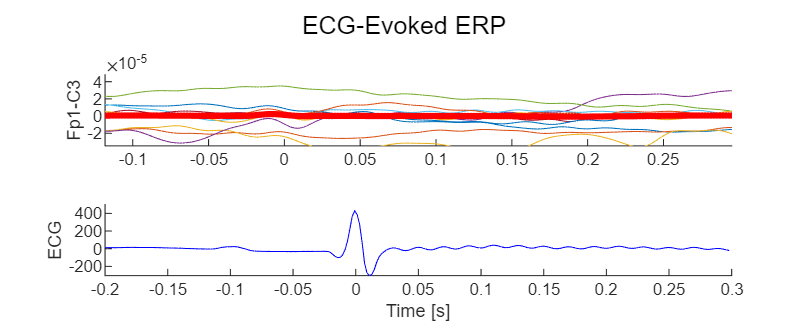

channels = {'Fp1-C3','C3-O1','Fp1-T3',...
    'T3-O1','Fp2-C4','C4-O2','Fp2-T4','T4-O2'};
figure('Position',[0 0 1000 400]);
for ch = 1
    subplot(2,1,ch)
    hold on
    plot(t,EEG_trials(1:10,:,ch)','linewidth',0.5)
    plot(t,EEG_mean(ch,:),'r','linewidth',3);
    ylabel(channels{ch});
    box off
end

subplot(2,1,2);
plot(t,ECG_mean,'b');
xlabel('Time [s]')
ylabel('ECG')
hold on;
% [y1,y2,h] = fill_between(t,ECG_mean-ECG_std,ECG_mean+ECG_std,1,'EdgeColor','none','FaceColor',[0 0 1],'FaceAlpha',0.2);
% y1.Color = 'none';
% y2.Color = 'none';
hold off;
box off;


sgtitle('ECG-Evoked ERP')